clc; clear;
dx=.01;
x=-2*pi:dx:2*pi;

Funciones

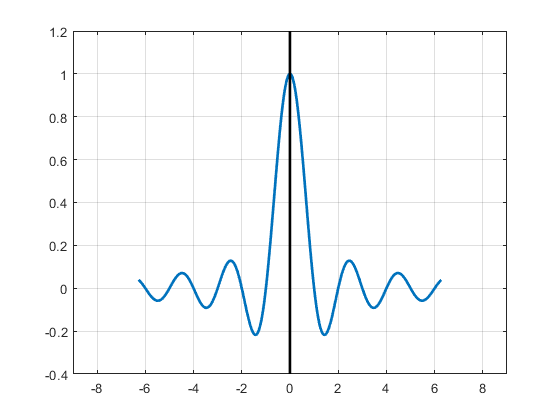

y1=sinc(x);
plot(x,y1,'LineWidth',2);
grid; axis([-9 9 -.4,1.2])

[m,xm]=max(y1);
x(xm);
line([x(xm),x(xm)],[-9 9],'color',[0 0 0],'LineWidth',2)


% plot(x(xm),m,'Linewidth',4,'Marker','*')


Aleatorios:

clear; clc;
r=8;
m=randi([-r r],3,10);
x=linspace(-1,1,length(m))

x =    -1.0000   -0.7778   -0.5556   -0.3333   -0.1111    0.1111    0.3333    0.5556    0.7778    1.0000


pr=zeros(1,length(m));
for i=1:1:length(m)
    pr(1,i)=mean(m(:,i));   
end
pf=mean(pr);
plot(x,m','LineWidth',4,'Marker','o')
grid; axis([-1,1,-r-1,r+1])
line([-1,1],[pf pf], 'color',[0 0 0],'LineWidth',4)
txt=['Prom=',num2str(pf)]

txt = 'Prom=-1.1'

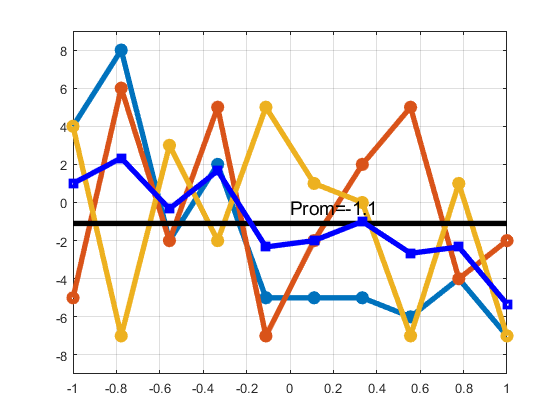

text(0,pf+.8,txt,'FontSize',14)
hold on
plot(x,pr','Linewidth',4,'Marker','sq','color',[0 0 1]);